clear all
clc
close all

% Sim vars
SIMTIME = 3600;
SIMSTEP = 0.1;
N = SIMTIME/SIMSTEP;
n_contr = 9;
n_obsv = 6;
time = 0:SIMSTEP:SIMTIME;


z33 = zeros(3,3);
% x = [Np, Ep, psip, u, v, r, tauN, tauE, tauPSI]
% Ship characteristics
[M, D, Athr] = loadvars();
A = [z33,    eye(3),    z33;
     z33, -inv(M)*D, inv(M);
     z33,       z33,   Athr];
B = [z33, z33, -Athr]';
Bv = [z33, inv(M), z33]';
C = [eye(3,9); z33 z33 eye(3,3)];
D = 0;
eig(A)

ans =          0
         0
    0.0011
    0.0035
         0
   -0.0069
   -0.0067
   -0.0050
   -0.0056


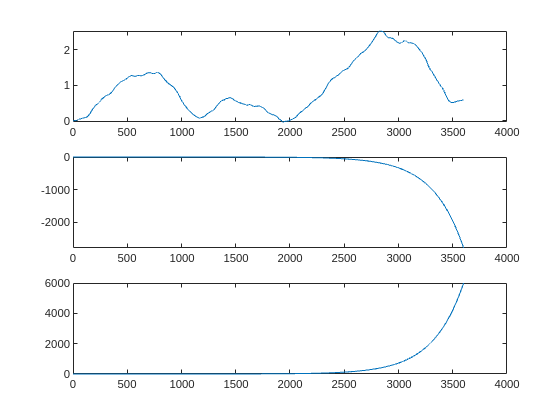

sigmav1 = [1e5, 1e5, 1e5]';
sigmav2 = [0.01, 0.01, 0.01, 0.01, 0.01, 0.01]';

% Stability
eig(A);
rank(ctrb(A, B));
rank(obsv(A, C));

x = zeros(n_contr, N+1);

% Test uncontrolled system
for i = 1:N
    u = zeros(3,1);
    v1 = normrnd(0, sigmav1);
    xdot = A * x(:,i) + B * u + Bv * v1;
    x(:, i+1) = x(:, i) + SIMSTEP * xdot;
end

figure
subplot(311),plot(time, x(1,:))
subplot(312),plot(time, x(2,:))
subplot(313),plot(time, x(3,:))

## LQR

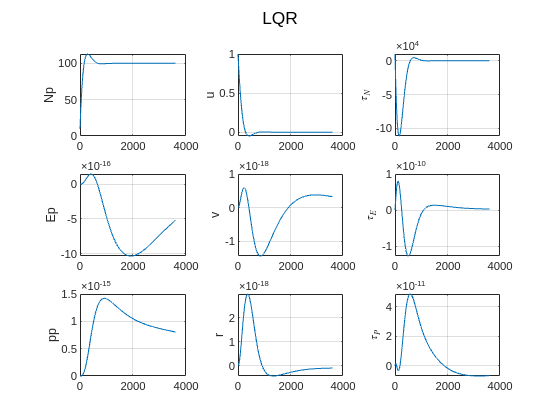

Q = diag([1e6, 1e6, 1e6, 0.01, 0.01, 0.01, 0.01, 0.01, 0.01]);
R = diag([0.01, 0.01, 0.01]);
K = lqr(A, B, Q, R);
Ak = A-B*K;
eig(Ak);

ref = zeros(n_contr, 1); 
x = zeros(n_contr, N+1);
x(:,1) = [10, 0, 0, 1, 0, 0, 10000, 0, 0];

% Ship loop
for i = 1:N
    ref(1:3) = [100;0;0];
    u = - K * (x(:,i) - ref);
    xdot = A * x(:,i) + B * u;% + Bv * v1;
    x(:, i+1) = x(:, i) + SIMSTEP * xdot;
end

figure
sgtitle("LQR")
subplot(331), plot(time, x(1, :)), grid, ylabel("Np")
subplot(334), plot(time, x(2, :)), grid, ylabel("Ep")
subplot(337), plot(time, x(3, :)), grid, ylabel("pp")

subplot(332), plot(time, x(4, :)), grid, ylabel("u")
subplot(335), plot(time, x(5, :)), grid, ylabel("v")
subplot(338), plot(time, x(6, :)), grid, ylabel("r")

subplot(333), plot(time, x(7, :)), grid, ylabel("$\tau_N$","Interpreter","latex")
subplot(336), plot(time, x(8, :)), grid, ylabel("$\tau_E$","Interpreter","latex")
subplot(339), plot(time, x(9, :)), grid, ylabel("$\tau_P$","Interpreter","latex")

## LQG

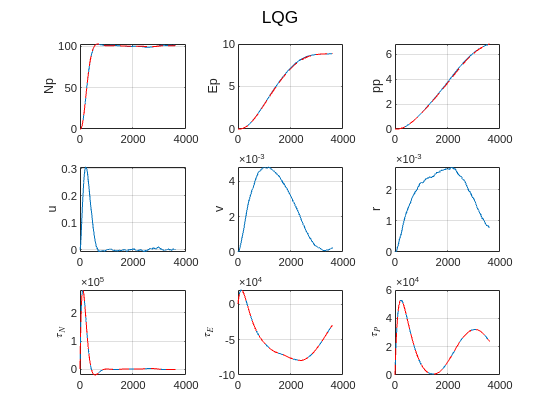

L = lqe(A, Bv, C, diag(sigmav1), diag(sigmav2));

%Aa = [A-L*C zeros(9,9);
%      L*C A-B*K];
%Ba = [Bv -L;
%      zeros(9,3)  L];

x = zeros(n_contr, N+1);
x(:,1) = [0, 0, 0, 0, 0, 0, 0, 0, 0];
y = zeros(n_obsv, N+1);
x_est = zeros(n_contr, N+1);
y_est = zeros(n_obsv, N+1);
ref = zeros(n_contr,1);

for i=1:N
    ref(1:3) = [100;10;10];
    u = -K * (x_est(:,i)-ref);
    x_est_dot = A * x_est(:,i)+B*u+L*(y(:,i)-y_est(:,i));
    x_est(:,i+1) = x_est(:,i) + SIMSTEP * x_est_dot;
    y_est(:,i+1) = C*x_est(:,i);
    
    v1 = normrnd(0, sigmav1);
    v2 = normrnd(0, sigmav2);
    xdot = A * x(:,i) +B * u + Bv * v1;
    x(:,i+1) = x(:,i) + SIMSTEP * xdot;
    y(:,i+1) = C*x(:,i) + v2;
end

figure
sgtitle("LQG")
subplot(331), plot(time, x(1, :)), hold on, plot(time, x_est(1,:), "r--"), grid, ylabel("Np")
subplot(332), plot(time, x(2, :)), hold on, plot(time, x_est(2,:), "r--"), grid, ylabel("Ep")
subplot(333), plot(time, x(3, :)), hold on, plot(time, x_est(3,:), "r--"), grid, ylabel("pp")

subplot(334), plot(time, x(4, :)), grid, ylabel("u")
subplot(335), plot(time, x(5, :)), grid, ylabel("v")
subplot(336), plot(time, x(6, :)), grid, ylabel("r")

subplot(337), plot(time, x(7, :)), hold on, plot(time, x_est(7,:), "r--"), grid, ylabel("$\tau_N$","Interpreter","latex")
subplot(338), plot(time, x(8, :)), hold on, plot(time, x_est(8,:), "r--"), grid, ylabel("$\tau_E$","Interpreter","latex")
subplot(339), plot(time, x(9, :)), hold on, plot(time, x_est(9,:), "r--"), grid, ylabel("$\tau_P$","Interpreter","latex")